clear; clc; close all;

% --- 1. Physical Dimensions ---
L_1 = 0.17;     % Crank arm length (meters)
L_3 = 0.15;     % Elevator horn length (meters)
x_c = 1.2;      % Horizontal distance to hinge
y_c = -0.8;     % Vertical distance to hinge
theta = linspace(-20, 20, 100) % Pilot input range (+/- 20 deg)

theta =   -20.0000  -19.5960  -19.1919  -18.7879  -18.3838  -17.9798  -17.5758  -17.1717  -16.7677  -16.3636  -15.9596  -15.5556  -15.1515  -14.7475  -14.3434  -13.9394  -13.5354  -13.1313  -12.7273  -12.3232  -11.9192  -11.5152  -11.1111  -10.7071  -10.3030   -9.8990   -9.4949   -9.0909   -8.6869   -8.2828   -7.8788   -7.4747   -7.0707   -6.6667   -6.2626   -5.8586   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.4141   -1.0101   -0.6061   -0.2020



% --- 2. Neutral Calibration (State: theta = 0, delta = 0) ---
start_angle = 220; % The "clocking" of the crank arm
th_n = 0;

% Coordinates of Crank Pin at Neutral
xa_n = L_1 * cosd(start_angle + th_n);
ya_n = L_1 * sind(start_angle + th_n);

% Coordinates of Hinge (Fixed)
xh = x_c; 
yh = y_c;

% Calculate the required Rod Length (L_2) to connect the points at Neutral
L_2 = sqrt((xh - xa_n)^2 + (yh + L_3 - ya_n)^2);

% Calculate geometric constants for rigging
S_n = sqrt((xh - xa_n)^2 + (yh - ya_n)^2);
Ga_n = atan2d(yh - ya_n, xh - xa_n);
Be_n = acosd((S_n^2 + L_3^2 - L_2^2) / (2 * S_n * L_3));
Phi = Ga_n + Be_n; % Rigging Constant

% --- 3. Simulation Loop ---
xa = L_1 * cosd(start_angle + theta);
ya = L_1 * sind(start_angle + theta);

S = sqrt((xh - xa).^2 + (yh - ya).^2);
Ga = atan2d(yh - ya, xh - xa);
Be = acosd((S.^2 + L_3^2 - L_2^2) ./ (2 .* S * L_3));

% Resulting Elevator Deflection
delta = (Ga + Be) - Phi

delta =   -24.4895  -23.9590  -23.4309  -22.9050  -22.3813  -21.8597  -21.3401  -20.8225  -20.3067  -19.7927  -19.2805  -18.7700  -18.2612  -17.7539  -17.2481  -16.7439  -16.2411  -15.7397  -15.2396  -14.7409  -14.2434  -13.7471  -13.2521  -12.7582  -12.2655  -11.7738  -11.2832  -10.7937  -10.3052   -9.8176   -9.3310   -8.8453   -8.3605   -7.8766   -7.3936   -6.9114   -6.4299   -5.9493   -5.4694   -4.9903   -4.5119   -4.0343   -3.5573   -3.0809   -2.6053   -2.1302   -1.6558   -1.1820   -0.7088   -0.2361



% --- 4. Visualization ---
figure('Color', 'w');
plot(theta, delta, 'b', 'LineWidth', 2); hold on;
 

grid on;
xlabel('Input Torque Tube Angle \theta (deg)');
ylabel('Elevator Deflection \delta (deg)');
title(' \delta(\theta)');

% Display results in Command Window
fprintf('--- Simulation Results ---\n');

--- Simulation Results ---


fprintf('Calculated Rod Length (L2): %.4f meters\n', L_2);

Calculated Rod Length (L2): 1.4359 meters


fprintf('Max Negative Deflection: %.2f deg\n', min(delta));

Max Negative Deflection: -24.49 deg


fprintf('Max Positive Deflection: %.2f deg\n', max(delta));

Max Positive Deflection: 22.92 deg


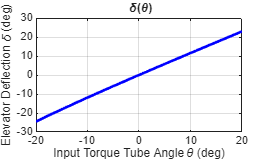


% --- 5. Export ---
exportgraphics(gca, 'B737_Elevator_Plot.png', 'Resolution', 300);